# Advanced Protections, Homework 2

Leighton Clarke

April 14, 2018

## Problem 1, part a

Read the csv file (prot2_hw2_2108.csv), convert the data into secondary values, and plot the voltages and currents:

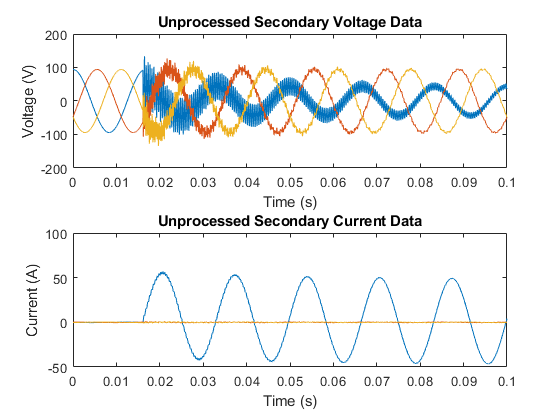

data = csvread('prot2_hw2_2108.csv');
PTR = 525000/115;
CTR = 800/5;
t0 = data(:,1);
Va = data(:,2)./PTR;
Vb = data(:,3)./PTR;
Vc = data(:,4)./PTR;
Ia = data(:,5)./CTR;
Ib = data(:,6)./CTR;
Ic = data(:,7)./CTR;
figure(1)
subplot(2,1,1)
plot(t0,Va,t0,Vb,t0,Vc)
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Unprocessed Secondary Voltage Data')
subplot(2,1,2)
plot(t0,Ia,t0,Ib,t0,Ic)
xlabel('Time (s)')
ylabel('Current (A)')
title('Unprocessed Secondary Current Data')

## Problem 1, part b

Simulate an RC filter with a cutoff frequency of 600Hz and apply it to each signal:

Here we determine the value of RC for this cutoff frequency and apply the recursive equation


$$v_k^{\left(o\right)} =\frac{\Delta t\cdot v_k^{\left(t\right)} +R\cdot C\cdot v_{k-1}^{\left(o\right)} }{\Delta t+R\cdot C}$$


to each signal.

fc = 600;
RC = 1 / (2*pi*fc);
Vaf = zeros(length(t0),1);
Vbf = zeros(length(t0),1);
Vcf = zeros(length(t0),1);
Iaf = zeros(length(t0),1);
Ibf = zeros(length(t0),1);
Icf = zeros(length(t0),1);

for k = 2:length(t0)
    Vaf(k)=((t0(k)-t0(k-1))*Va(k)+RC*Vaf(k-1))/((t0(k)-t0(k-1))+RC);
    Vbf(k)=((t0(k)-t0(k-1))*Vb(k)+RC*Vbf(k-1))/((t0(k)-t0(k-1))+RC);
    Vcf(k)=((t0(k)-t0(k-1))*Vc(k)+RC*Vcf(k-1))/((t0(k)-t0(k-1))+RC);
    Iaf(k)=((t0(k)-t0(k-1))*Ia(k)+RC*Iaf(k-1))/((t0(k)-t0(k-1))+RC);
    Ibf(k)=((t0(k)-t0(k-1))*Ib(k)+RC*Ibf(k-1))/((t0(k)-t0(k-1))+RC);
    Icf(k)=((t0(k)-t0(k-1))*Ic(k)+RC*Icf(k-1))/((t0(k)-t0(k-1))+RC);
end

The filter's output voltages and currents are shown below.

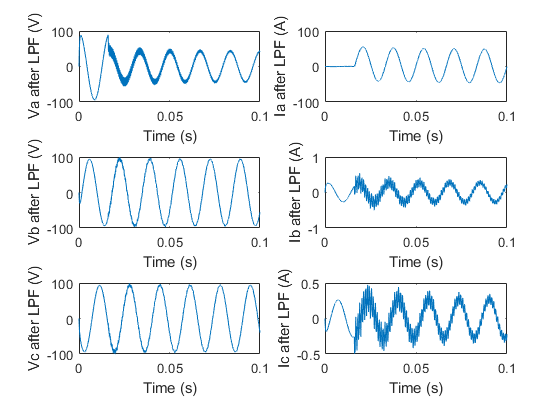

figure(2)
subplot(3,2,1)
plot(t0,Vaf)
xlabel('Time (s)')
ylabel('Va after LPF (V)')
subplot(3,2,2)
plot(t0,Iaf)
xlabel('Time (s)')
ylabel('Ia after LPF (A)')
subplot(3,2,3)
plot(t0,Vbf)
xlabel('Time (s)')
ylabel('Vb after LPF (V)')
subplot(3,2,4)
plot(t0,Ibf)
xlabel('Time (s)')
ylabel('Ib after LPF (A)')
subplot(3,2,5)
plot(t0,Vcf)
xlabel('Time (s)')
ylabel('Vc after LPF (V)')
subplot(3,2,6)
plot(t0,Icf)
xlabel('Time (s)')
ylabel('Ic after LPF (A)')

## Problem 1, part c

Interpolate the filtered signals with a sample rate of 16 samples per cycle:

First we define the sampling frequency and period and create a new time array (ts), then we use MATLAB's 'interp1' function to extract the desired data.

Nsc = 16;
fs = Nsc * 60;
Ts = 1 /fs;
ts = 0:Ts:t0(end);
Vafi = interp1(t0, Vaf, ts);
Vbfi = interp1(t0, Vbf, ts);
Vcfi = interp1(t0, Vcf, ts);
Iafi = interp1(t0, Iaf, ts);
Ibfi = interp1(t0, Ibf, ts);
Icfi = interp1(t0, Icf, ts);

## Problem 1, part d

Implement digital filters to obtain just the fundamental of the voltage and current signals:

Digital filters require a vector of coefficients that are applied to the input data. A common method in protections systems is to isolate the fundamental using the discrete Fourier transform (DFT). The coefficients for this transform are defined as follows:


$$Ck_n =\left(\frac{2}{N}\right)\left(\mathrm{cos}\left(\frac{2\pi \mathrm{nk}}{N}\right)+\mathrm{jsin}\left(\frac{2\pi \mathrm{nk}}{N}\right)\right)$$


where k is the harmonic (therefore 1 for the fundamental), N is the number of samples per fundamental cycle, and n is the coefficient index. Because there are both real and imaginary components, we must create two filters and coefficient vectors - one for the cosine terms (A) and one for the sine terms (B). Each of these vectors need only contain coefficients for one cycle.

n = 1:Nsc;
A = (2/Nsc)*cos(2*pi*n/Nsc);
B = (2/Nsc)*sin(2*pi*n/Nsc);

Now we can use MATLAB's built-in 'filter' function to apply these filters to the data.

VaRe = filter(A, 1, Vafi);
VbRe = filter(A, 1, Vbfi);
VcRe = filter(A, 1, Vcfi);
IaRe = filter(A, 1, Iafi);
IbRe = filter(A, 1, Ibfi);
IcRe = filter(A, 1, Icfi);
VaIm = filter(B, 1, Vafi);
VbIm = filter(B, 1, Vbfi);
VcIm = filter(B, 1, Vcfi);
IaIm = filter(B, 1, Iafi);
IbIm = filter(B, 1, Ibfi);
IcIm = filter(B, 1, Icfi);

The output of the cosine filter for each voltage and current is shown below.

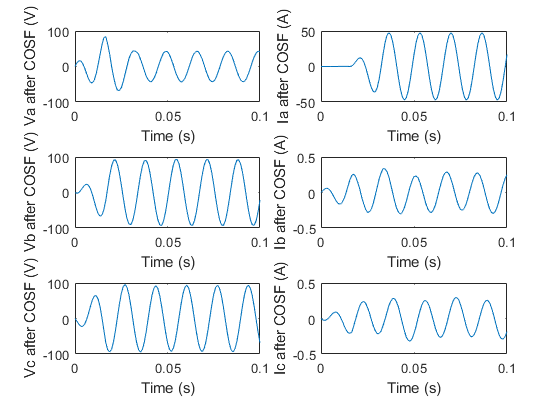

figure(3)
subplot(3,2,1)
plot(ts,VaRe)
xlabel('Time (s)')
ylabel('Va after COSF (V)')
subplot(3,2,2)
plot(ts,IaRe)
xlabel('Time (s)')
ylabel('Ia after COSF (A)')
subplot(3,2,3)
plot(ts,VbRe)
xlabel('Time (s)')
ylabel('Vb after COSF (V)')
subplot(3,2,4)
plot(ts,IbRe)
xlabel('Time (s)')
ylabel('Ib after COSF (A)')
subplot(3,2,5)
plot(ts,VcRe)
xlabel('Time (s)')
ylabel('Vc after COSF (V)')
subplot(3,2,6)
plot(ts,IcRe)
xlabel('Time (s)')
ylabel('Ic after COSF (A)')

## Problem 1, part e

Determine the magnitudes and phases of the phasors associated with the voltages and currents, using the a-phase voltage as the reference:

The relationship between a voltage phasor and the time-domain equation is shown below:


$$V_o \left(\mathrm{cos}\left(\omega t+\theta_V \right)+j\cdot \mathrm{sin}\left(\omega t+\theta_V \right)\right)=\sqrt{2}\cdot \overline{V} \cdot e^{j\omega t}$$


where $V_0$ is the time-domain signal amplitude. The time-domain function can also be referred to as the sum of its real (cosine) and imaginary (sine) components, which were already separated in part d. Therefore, we can create an array containing an RMS value at each datapoint for the voltage and current data by sweeping the time value:


$$\overline{V} =\frac{V_{\mathrm{cos}} \left(t\right)+j\cdot V_{\mathrm{sin}} \left(t\right)}{\sqrt{2}}\cdot e^{-j\omega t}$$


Vap = (1/sqrt(2))*(VaRe+1i*VaIm).*exp(-1i*2*pi*60*ts);
Vbp = (1/sqrt(2))*(VbRe+1i*VbIm).*exp(-1i*2*pi*60*ts);
Vcp = (1/sqrt(2))*(VcRe+1i*VcIm).*exp(-1i*2*pi*60*ts);
Iap = (1/sqrt(2))*(IaRe+1i*IaIm).*exp(-1i*2*pi*60*ts);
Ibp = (1/sqrt(2))*(IbRe+1i*IbIm).*exp(-1i*2*pi*60*ts);
Icp = (1/sqrt(2))*(IcRe+1i*IcIm).*exp(-1i*2*pi*60*ts);

We will take the final value in each phasor array as the steady-state value. We subtract the angle of the a-phase voltage phasor from each angle, so that it is the reference angle.

d = 180/pi;
Vastr = ['Va = ' num2str(abs(Vap(end))) ' V, angle 0 degrees'];
Vbstr = [newline 'Vb = ' num2str(abs(Vbp(end))) ' V, angle ' ...
    num2str(angle(Vbp(end))*d - angle(Vap(end))*d) ' degrees'];
Vcstr = [newline 'Vc = ' num2str(abs(Vcp(end))) ' V, angle ' ...
    num2str(angle(Vcp(end))*d - angle(Vap(end))*d) ' degrees'];
Iastr = [newline 'Ia = ' num2str(abs(Iap(end))) ' A, angle ' ...
    num2str(angle(Iap(end))*d - angle(Vap(end))*d) ' degrees'];
Ibstr = [newline 'Ib = ' num2str(abs(Ibp(end))) ' A, angle ' ...
    num2str(angle(Ibp(end))*d - angle(Vap(end))*d) ' degrees'];
Icstr = [newline 'Ic = ' num2str(abs(Icp(end))) ' A, angle ' ...
    num2str(angle(Icp(end))*d - angle(Vap(end))*d) ' degrees'];
disp([Vastr Vbstr Vcstr Iastr Ibstr Icstr])

Va = 30.5467 V, angle 0 degrees
Vb = 66.6804 V, angle -120.1299 degrees
Vc = 65.8348 V, angle 119.8994 degrees
Ia = 33.6738 A, angle -86.5995 degrees
Ib = 0.18707 A, angle -36.9869 degrees
Ic = 0.20424 A, angle -147.1831 degrees


Plots comparing the original and phasor magnitude values for each voltage and current are shown below:

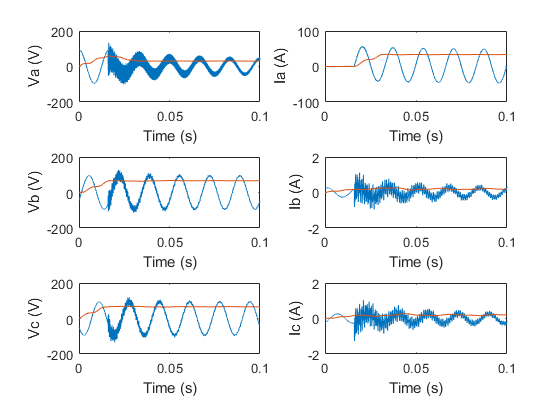

figure(4)
subplot(3,2,1)
plot(t0, Va)
hold on
plot(ts,abs(Vap))
xlabel('Time (s)')
ylabel('Va (V)')
subplot(3,2,3)
plot(t0, Vb)
hold on
plot(ts,abs(Vbp))
xlabel('Time (s)')
ylabel('Vb (V)')
subplot(3,2,5)
plot(t0, Vc)
hold on
plot(ts,abs(Vcp))
xlabel('Time (s)')
ylabel('Vc (V)')
subplot(3,2,2)
plot(t0, Ia)
hold on
plot(ts,abs(Iap))
xlabel('Time (s)')
ylabel('Ia (A)')
subplot(3,2,4)
plot(t0, Ib)
hold on
plot(ts,abs(Ibp))
xlabel('Time (s)')
ylabel('Ib (A)')
subplot(3,2,6)
plot(t0, Ic)
hold on
plot(ts,abs(Icp))
xlabel('Time (s)')
ylabel('Ic (A)')

The angles of each phasor are plotted below as well (without using the a-phase voltage angle as a reference):

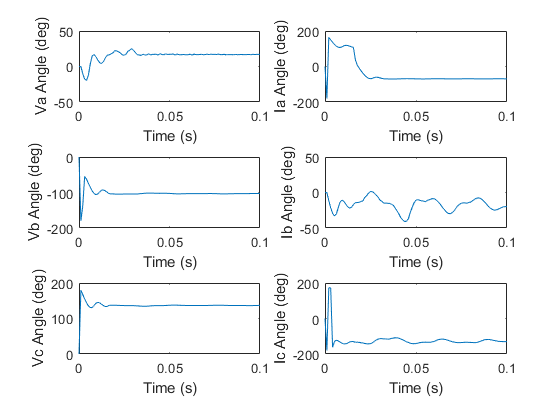

figure(5)
subplot(3,2,1)
plot(ts,angle(Vap)*d)
ylabel('Va Angle (deg)')
xlabel('Time (s)')
subplot(3,2,2)
plot(ts,angle(Iap)*d)
ylabel('Ia Angle (deg)')
xlabel('Time (s)')
subplot(3,2,3)
plot(ts,angle(Vbp)*d)
ylabel('Vb Angle (deg)')
xlabel('Time (s)')
subplot(3,2,4)
plot(ts,angle(Ibp)*d)
ylabel('Ib Angle (deg)')
xlabel('Time (s)')
subplot(3,2,5)
plot(ts,angle(Vcp)*d)
ylabel('Vc Angle (deg)')
xlabel('Time (s)')
subplot(3,2,6)
plot(ts,angle(Icp)*d)
ylabel('Ic Angle (deg)')
xlabel('Time (s)')

The phasor angles are plotted once more below with the angle of the a-phase voltage used as the reference:

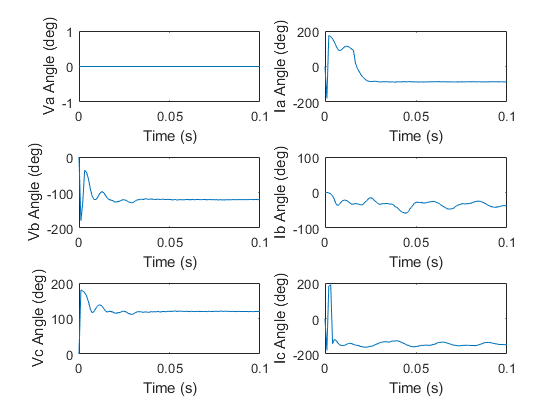

figure(6)
subplot(3,2,1)
plot(ts,angle(Vap)*d - angle(Vap)*d)
ylabel('Va Angle (deg)')
xlabel('Time (s)')
subplot(3,2,2)
plot(ts,angle(Iap)*d - angle(Vap)*d)
ylabel('Ia Angle (deg)')
xlabel('Time (s)')
subplot(3,2,3)
plot(ts,angle(Vbp)*d - angle(Vap)*d)
ylabel('Vb Angle (deg)')
xlabel('Time (s)')
subplot(3,2,4)
plot(ts,angle(Ibp)*d - angle(Vap)*d)
ylabel('Ib Angle (deg)')
xlabel('Time (s)')
subplot(3,2,5)
plot(ts,angle(Vcp)*d - angle(Vap)*d)
ylabel('Vc Angle (deg)')
xlabel('Time (s)')
subplot(3,2,6)
plot(ts,angle(Icp)*d - angle(Vap)*d)
ylabel('Ic Angle (deg)')
xlabel('Time (s)')

## Problem 1, part f

Finally, we must calculate the fault voltages and currents at the circuit breaker's location using traditional methods. Because this is a single-line-to-ground phase, we will create an equivalent circuit with the sequence components in series. There is no transformer, so each sequence impedance will simpy be the sum of the source and line impedances. The positive, negative, and zero sequence currents are equal for this type of fault. (Eq. Circuit diagram and equations in Chapman, ch. 13)

Zs1 = 2 +1j*30;
Zs2 = Zs1;
Zs0 = Zs1;
ZL1 = (0.073 + 1j*0.8) * 20;
ZL2 = ZL1;
ZL0 = (0.1 + 1j*2.3) * 20;
Z1 = Zs1 + ZL1;
Z2 = Zs2 + ZL2;
Z0 = Zs0 + ZL0;
E = 525000 / sqrt(3);
IA1 = E / (Z1 + Z2 + Z0);
IA2 = IA1;
IA0 = IA1;
VA1 = E - IA1*Zs1;
VA2 = -IA2*Zs2;
VA0 = -IA0*Zs0;
VA = (VA1 + VA2 + VA0)/PTR;
IA = (IA1 + IA2 + IA0)/CTR;
a = exp(1j*2*pi/3);
VB = ((a^2)*VA1 + a*VA2 + VA0)/PTR;
VC = (a*VA1 + (a^2)*VA2 + VA0)/PTR;
IB = (IA0 + IA1*a^2 + IA2*a)/CTR;
IC = (IA0 + a*IA1 + (a^2)*IA2)/CTR;

A comparison of the phasor values calculated using the filtering algorithm and using the conventional methods is shown in the table below:

Signal = {'Va'; 'Vb'; 'Vc'; 'Ia'; 'Ib'; 'Ic'};
Relay_Magnitude_V = [abs(Vap(end));abs(Vbp(end));abs(Vcp(end)); ...
    abs(Iap(end));abs(Ibp(end));abs(Icp(end))];
Relay_Angle_deg = [0;angle(Vbp(end))*d - angle(Vap(end))*d; ...
    angle(Vcp(end))*d - angle(Vap(end))*d;angle(Iap(end))*d - angle(Vap(end))*d; ...
    angle(Ibp(end))*d - angle(Vap(end))*d;angle(Icp(end))*d - angle(Vap(end))*d];
Calculated_Magnitude_V = [abs(VA);abs(VB);abs(VC);abs(IA);abs(IB);abs(IC)];
Calculated_Angle_deg = [angle(VA)*d;angle(VB)*d;angle(VC)*d; ...
    angle(IA)*d;angle(IB)*d;angle(IC)*d];
T = table(Signal, Relay_Magnitude_V, Relay_Angle_deg, Calculated_Magnitude_V, ...
    Calculated_Angle_deg);
T.Properties.VariableUnits = {'' 'V' 'deg' 'V' 'deg'};
disp(T)

    Signal    Relay_Magnitude_V    Relay_Angle_deg    Calculated_Magnitude_V    Calculated_Angle_deg
    ______    _________________    _______________    ______________________    ____________________

    'Va'       30.547                    0                30.823                0.10973             
    'Vb'        66.68              -120.13                66.395                   -120             
    'Vc'       65.835                119.9                66.395                    120             
    'Ia'       33.674              -86.599                33.758                -86.281             
    'Ib'      0.18707              -36.987            2.9296e-15                 14.036             
    'Ic'      0.20424              -147.18            2.9296e-15                 14.036             



As seen in the table, the voltages are very similar between the digital relay and the traditionally calculated values. However, the b-phase and c-phase currents are different. Traditionally, we assume that in a single-line-to-ground fault, the current in the two non-faulted lines goes to zero, making the angle irrelevant. However, the data does actually include small (<1A) currents in these phases. This comparison shows that the traditional method is fairly accurate for voltages and fault current, but may not always match real-life fault behavior. That being said, these currents are so small that they are probably negligible.